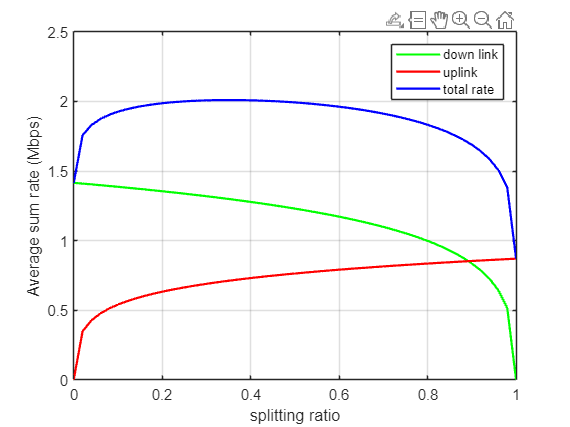

clc; clear variables; close all;

 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 1;   %Source to near user distance    
dsf = 9;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsn = (abs(hsn)).^2;
hsf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = (abs(hsf)).^2;
hnf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = (abs(hnf)).^2;



Pt = 30;    % 发送功率（dBm）
pt = 10.^(Pt/10);    % 发送功率（线性尺度）
B = 1000000;
B1 = B/2;
N0_dBm=-60;                % Noise spectral density (in dBm/Hz)
N0=10^(N0_dBm/10)*B;          % Linear noise PSD in mW/Hz
N01 = (10^(N0_dBm/10))*B1;      %linear noise for swipt oma
snr = pt/N0;       %SNR in linear
snr1 = pt/(N01);       %SNR in linear(swipt oma)
SNR = 10*log10(snr);%SNR in dB
 
%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0:0.02:1; %power splitting coefficient
del = 10^-6; %a small number
pa = 0.7;                  % PA efficiency

%Some buffers
pn = zeros(1,length(frac));
pf = zeros(1,length(frac));

csn = zeros(1,length(frac));
cfs = zeros(1,length(frac));
ph = zeros(1,length(frac));
sum_s = zeros(1,length(frac));
un = zeros(1,length(frac));
uf = zeros(1,length(frac));
sum_uplink = zeros(1,length(frac));
sum= zeros(1,length(frac));

for u = 1:length(frac)    
   
    

    %Amount of power harvested by near user
    ph = pt*gsn.*frac(u)*eff/(1+dsn^eta);
    

    %SNIR for each user
    
    sSNRn = (1-frac(u))*snr1.*gsn./(dsn^eta);   %near user, swipt SNR
    sSNRf = (1-frac(u))*snr1.*gsf./(dsf^eta);
   
    %Achievable rate of near user
 
    Rsn = 0.5*0.2*log2(1 + sSNRn);    %data rate for near user, swipt
  
    %Achievable rate of far user
 
    Rfs= 0.5*0.2*log2(1 + sSNRf);       %data rate for far user, swipt
 
    %energy harvest
    E_PSn = frac(u)  .* eff .* (gsn) .* snr1;
    E_PSf = frac(u)  .* eff .* (gsf) .* snr1;

    %Achieveable data rate(uplink)
    R_uplink_n = 0.5*0.2*log2(1 + ((gsn).*  frac(u)  .* eff .* (gsn) .* snr1* pa)./(dsn^eta)^2);
    R_uplink_f = 0.5*0.2*log2(1 + ((gsf).*  frac(u)  .* eff .* (gsf) .* snr1* pa)./(dsf^eta)^2);


    %calculate average rate for each user and the sum rate
 
    csn(u) = mean(Rsn);%swipt near
    cfs(u) = mean(Rfs);%swipt far
    un(u) = mean(R_uplink_n);%swipt near
    uf(u) = mean(R_uplink_f);
 

  
    sum_s(u) = csn(u) + cfs(u);%sum rate swipt
    sum_uplink (u) = un(u) + uf(u);
    sum(u) = sum_s(u)+sum_uplink (u);
    
   

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);

 

figure;
plot(frac, sum_s, 'g', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
plot(frac,sum_uplink, 'r', 'LineWidth', 1.5, 'MarkerSize', 6);
plot(frac,sum, 'b', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('down link', 'uplink','total rate');
xlabel('splitting ratio');
ylabel('Average sum rate (Mbps)');